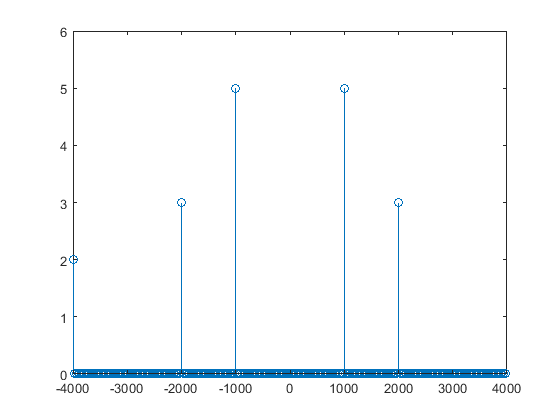

% Nyguist rate and aliasing effect
T=50;
N=256;
F = 1000;
Fs = 8000; %Sampling frequency
t = 0:1/Fs:T;
x = 10*cos(2*pi*F*t) + 6*cos(2*2*pi*F*t) + 2*cos(2*4*pi*F*t); %input signal
Y = fft(x,N); %Fast fourier transform
Y = fftshift(Y);% Shifting FFT to center
Y = abs(Y);
Y = Y/N;
f = -1*(Fs/2):Fs/N:(Fs/2)-1;
figure(1);
stem(f,Y)  %fs = 2*fm => aliasing effect

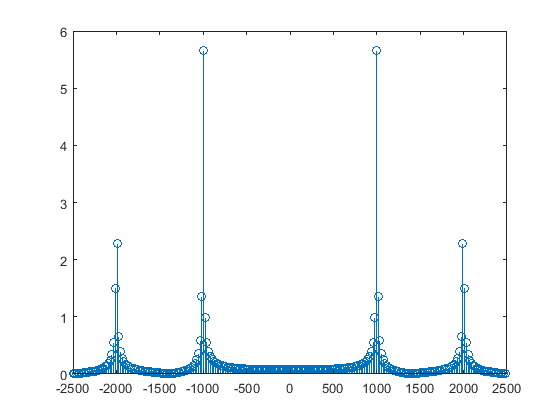

T=50;
N=256;
F = 1000;
Fs = 5000;
t = 0:1/Fs:T;
x = 10*cos(2*pi*F*t) + 6*cos(2*2*pi*F*t) + 2*cos(2*4*pi*F*t);
Y = fft(x,N);
Y = fftshift(Y);
Y = abs(Y);
Y = Y/N;
f = -1*(Fs/2):Fs/N:(Fs/2)-1;
figure(2);
stem(f,Y) % fs<2*fm => aliasing effect 

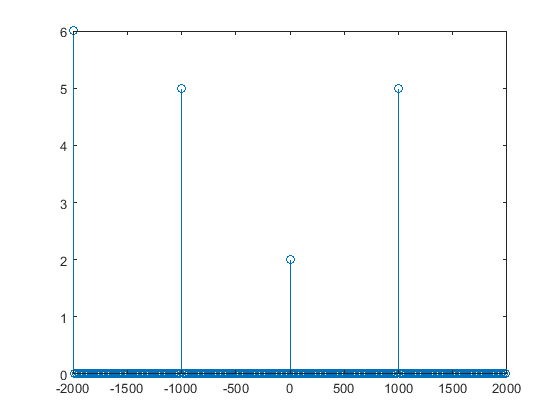

T=50;
N=256;
F = 1000;
Fs = 4000;
t = 0:1/Fs:T;
x = 10*cos(2*pi*F*t) + 6*cos(2*2*pi*F*t) + 2*cos(2*4*pi*F*t);
Y = fft(x,N);
Y = fftshift(Y);
Y = abs(Y);
Y = Y/N;
f = -1*(Fs/2):Fs/N:(Fs/2)-1;
figure(3);
stem(f,Y) % fs<2*fm => aliasing effect